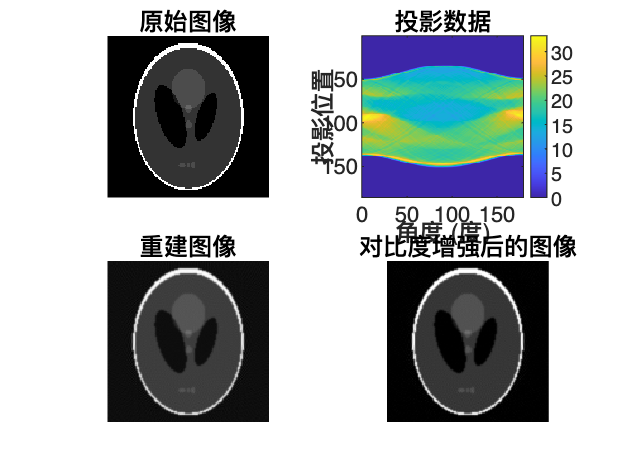

% 生成示例投影数据
theta = 0:179; % 投影角度
I = phantom(128); % 生成 Shepp-Logan 幻影图像
R = radon(I, theta); % 计算 Radon 变换（投影数据）

% 绘制原始图像和投影数据
figure;
subplot(2,2,1);
imshow(I, []);
title('原始图像');

subplot(2,2,2);
imagesc(theta, 1:size(R,1), R);
title('投影数据');
xlabel('角度 (度)');
ylabel('投影位置');
colorbar;

% 使用滤波反投影算法重建图像
I_reconstructed = iradon(R, theta, 'linear', 'Ram-Lak', 1, 128);

% 绘制重建的图像
subplot(2,2,3);
imshow(I_reconstructed, []);
title('重建图像');

% 图像处理：对比度增强
I_enhanced = imadjust(I_reconstructed);

% 绘制对比度增强后的图像
subplot(2,2,4);
imshow(I_enhanced, []);
title('对比度增强后的图像');